%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Sound Analysis with MATLAB Implementation    %
%                                                %
% Author: M.Sc. Eng. Hristo Zhivomirov  04/01/14 %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear, clc, close all

## get a section of the sound file

[x, fs] = audioread('Nom.wav');	% load an audio file
x = x(:, 1);                     	% get the first channel
N = length(x);                   	% signal length
to = (0:N-1)/fs;                    % time vector

## plot the signal oscillogram

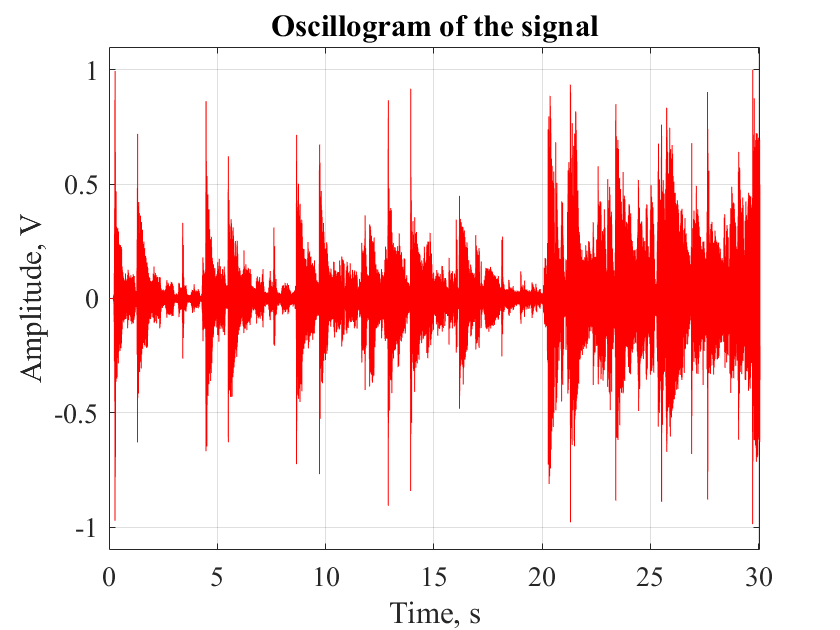

figure(1)
plot(to, x, 'r')
xlim([0 max(to)])
ylim([-1.1*max(abs(x)) 1.1*max(abs(x))])
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14)
xlabel('Time, s')
ylabel('Amplitude, ')
title('Oscillogram of the signal')

## plot the signal spectrum

spectral analysis

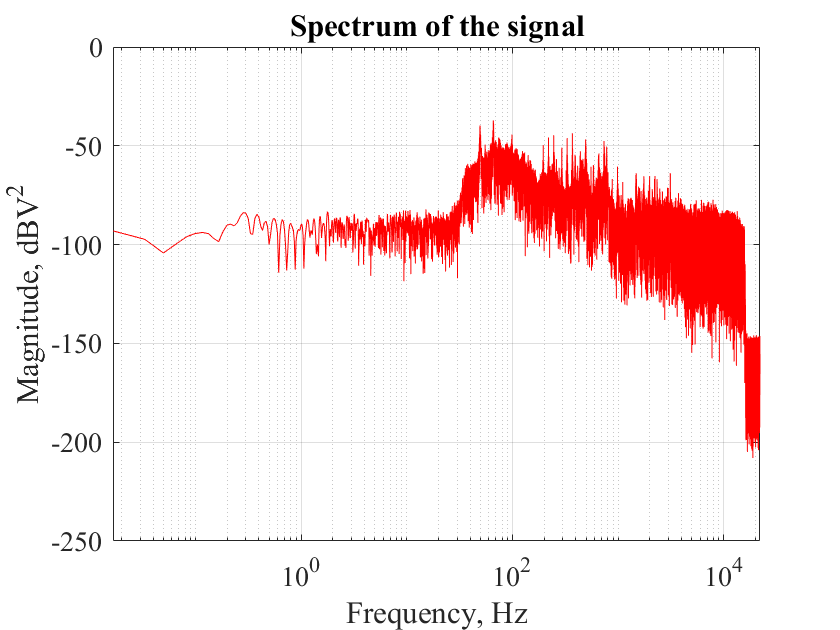

winlen = N;
win = blackman(winlen, 'periodic');
nfft = round(2*winlen);
[PS, f] = periodogram(x, win, nfft, fs, 'power');
X = 10*log10(PS);

% plot the spectrum
figure(2)
semilogx(f, X, 'r')
xlim([0 max(f)])
grid on
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14)
title('Spectrum of the signal')
xlabel('Frequency, Hz')
ylabel('Magnitude, dBV^2')